clc; clear all; close all; 
img_path = fullfile('fundus_images'); % Definir la ruta relativa de las imagenes RFI.
metadata_path = fullfile('metadata', 'metadata.csv'); % Definir la ruta relativa de la tabla metadata.
T = readtable(metadata_path);

factor_reduccion = 0.20; 

1.

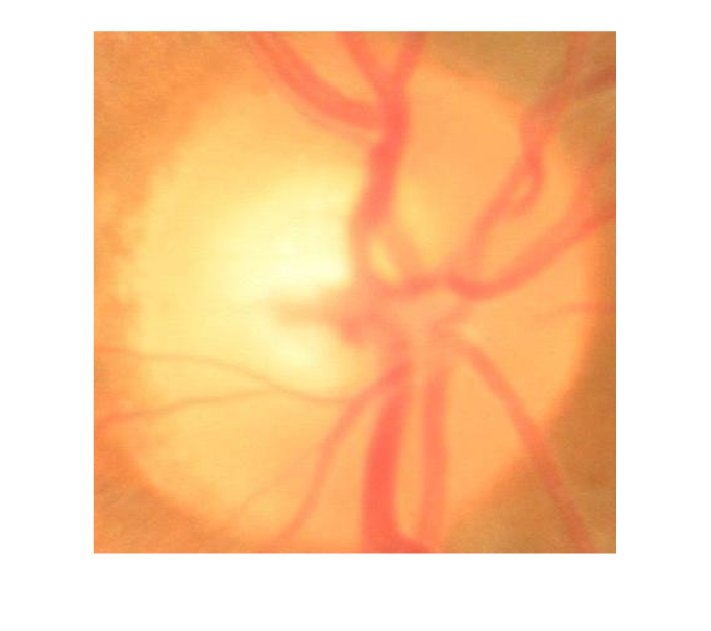

RGB = imread(string(fullfile(img_path, T{9,1})));

RGB1 = imresize(RGB, [NaN, 3000], 'bicubic');

R1=RGB1(:,:,1);
G1=RGB1(:,:,2);
B1=RGB1(:,:,3);

margen1=250;
centroideY1=1300;
centroideX1=1910;

OD_zoomR1 = R1(centroideY1-margen1:centroideY1+margen1, centroideX1-margen1:centroideX1+margen1);
OD_zoomG1 = G1(centroideY1-margen1:centroideY1+margen1, centroideX1-margen1:centroideX1+margen1);
OD_zoomB1 = B1(centroideY1-margen1:centroideY1+margen1, centroideX1-margen1:centroideX1+margen1);
OD_zoomRGB1 = cat(3, OD_zoomR1, OD_zoomG1, OD_zoomB1);%Para juntar las 3 layers
imshow(OD_zoomRGB1);

%imwrite(OD_zoomRGB1, 'Template1.jpg');

R1m=medfilt2(R1,[3 3],"symmetric");
G1m=medfilt2(G1,[3 3],"symmetric");
B1m=medfilt2(B1,[3 3],"symmetric");

[histR1, binR1] = imhist(R1m);
[histG1, binG1] = imhist(G1m);
[histB1, binB1] = imhist(B1m);

meanHistRGBTemplate=[histR1 histG1 histB1];
save('meanHistRGBTemplate.mat', 'meanHistRGBTemplate');